x=50;y=80;g=10;w0=2;w1=1;v0=100;
g1_r= @(t,theta0) v0.*cos(theta0).*t

g1_r = function_handle with value:
    @(t,theta0)v0.*cos(theta0).*t


g2_r= @(t,theta0) v0.*sin(theta0).*t-1/2.*g.*t.^2

g2_r = function_handle with value:
    @(t,theta0)v0.*sin(theta0).*t-1/2.*g.*t.^2



g1_l= @(t) x+w0*t+w1*t^2;
g2_l= @() y;

f1=@(t,theta0) g1_r(t,theta0)-g1_l(t)

f1 = function_handle with value:
    @(t,theta0)g1_r(t,theta0)-g1_l(t)


f2=@(t,theta0) g2_r(t,theta0)-g2_l()

f2 = function_handle with value:
    @(t,theta0)g2_r(t,theta0)-g2_l()


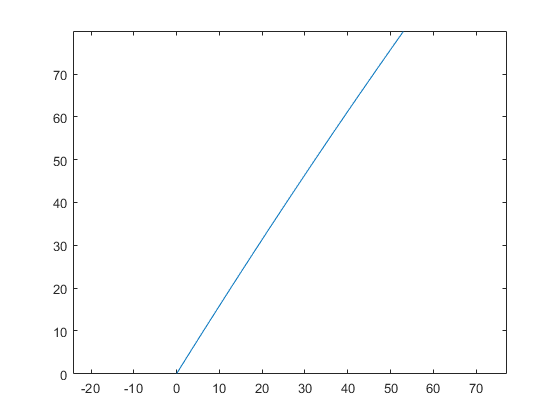

axis equal

f1s=sym(f1)

$$f1s = 100\,t\,\cos\left(\theta_{0}\right)-2\,t-t^{2}-50$$

f2s=sym(f2)

$$f2s = -5\,t^{2}+100\,\sin\left(\theta_{0}\right)\,t-80$$

J1s=jacobian([f1s,f2s],[t,theta0])

$$J1s = \left(\begin{array}{cc} 100\,\cos\left(\theta_{0}\right)-2\,t-2 & -100\,t\,\sin\left(\theta_{0}\right)\\ 100\,\sin\left(\theta_{0}\right)-10\,t & 100\,t\,\cos\left(\theta_{0}\right) \end{array}\right)$$

J=matlabFunction(J1s)

J = function_handle with value:
    @(t,theta0)reshape([t.*-2.0+cos(theta0).*1.0e+2-2.0,t.*-1.0e+1+sin(theta0).*1.0e+2,t.*sin(theta0).*-1.0e+2,t.*cos(theta0).*1.0e+2],[2,2])


F=matlabFunction([f1s;f2s])

F = function_handle with value:
    @(t,theta0)[t.*-2.0+t.*cos(theta0).*1.0e+2-t.^2-5.0e+1;t.*sin(theta0).*1.0e+2-t.^2.*5.0-8.0e+1]


xy = [1;pi/6]

xy =     1.0000
    0.5236


[xy, num] = newton_method(xy,J,F)

xy =     1.0019
    1.0133


num = 3

time = linspace(0,xy(1),100);
xy(2)*360/(2*pi)

ans = 58.0570

g1_l(xy(1))

ans = 53.0076

x = g1_r(time,xy(2))

x =          0    0.5354    1.0709    1.6063    2.1417    2.6772    3.2126    3.7480    4.2834    4.8189    5.3543    5.8897    6.4252    6.9606    7.4960    8.0315    8.5669    9.1023    9.6377   10.1732   10.7086   11.2440   11.7795   12.3149   12.8503   13.3858   13.9212   14.4566   14.9921   15.5275   16.0629   16.5983   17.1338   17.6692   18.2046   18.7401   19.2755   19.8109   20.3464   20.8818   21.4172   21.9526   22.4881   23.0235   23.5589   24.0944   24.6298   25.1652   25.7007   26.2361


y = g2_r(time,xy(2))

y =          0    0.8583    1.7155    2.5717    3.4269    4.2810    5.1342    5.9863    6.8374    7.6874    8.5365    9.3845   10.2315   11.0775   11.9224   12.7663   13.6092   14.4511   15.2919   16.1318   16.9706   17.8083   18.6451   19.4808   20.3155   21.1492   21.9818   22.8135   23.6441   24.4736   25.3022   26.1297   26.9562   27.7817   28.6062   29.4296   30.2520   31.0734   31.8938   32.7131   33.5314   34.3487   35.1650   35.9802   36.7944   37.6076   38.4198   39.2310   40.0411   40.8502


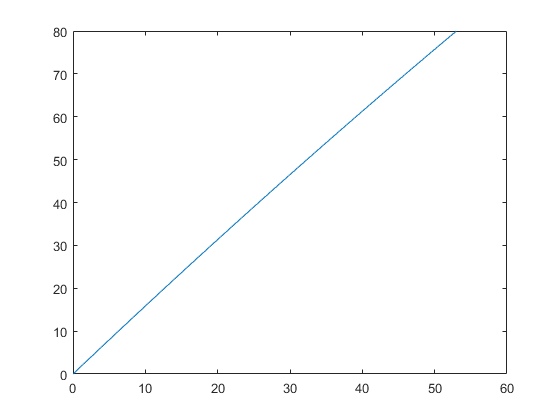

plot(x,y)

function [xy,num] = newton_method(xy,J,F)
%Newton method
num=0;
EROR = Inf;
error = 0.01;
while EROR>error
    EROR=xy;
    xy=xy - (inv( J(xy(1),xy(2)) ) * F(xy(1),xy(2)));
    num=num+1;
    EROR = norm(EROR - xy);
end
end